% CHECKING FRAME NUM & RATE


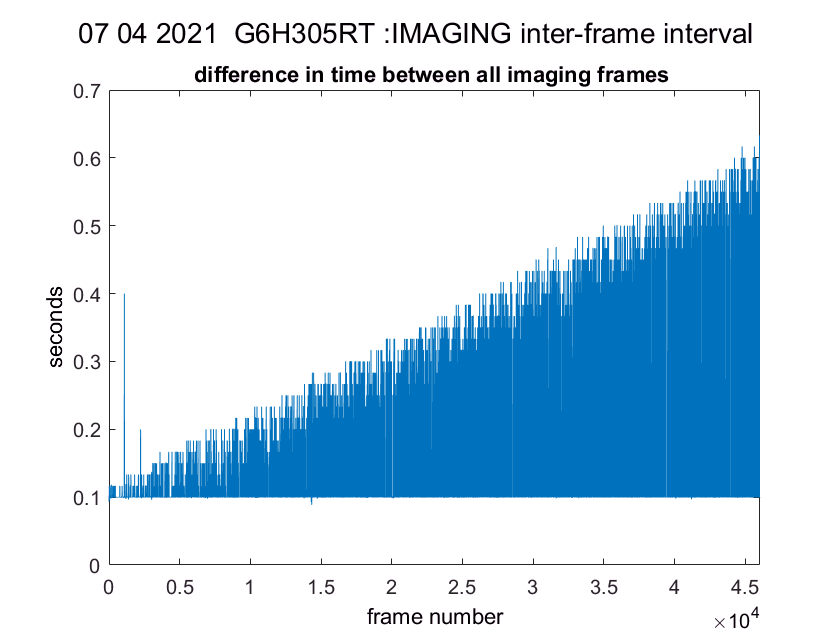

% CHECKing IMAGING FRAME TIMES
% to make sure our imaging frames are equal intervals apart

diffFrameT = diff(frameT);

figure
clear titleText
titleText = ':IMAGING inter-frame interval';
suptitle(sprintf('%s ',date,subjName,titleText));

plot(diff(frameT)) % plotting the difference between each successive value in frameT
xlim([0 length(frameT)])
ylim([0 0.7])
xlabel('frame number')
ylabel('seconds')
clear titleText
titleText = 'difference in time between all imaging frames';
title(sprintf('%s ',titleText))

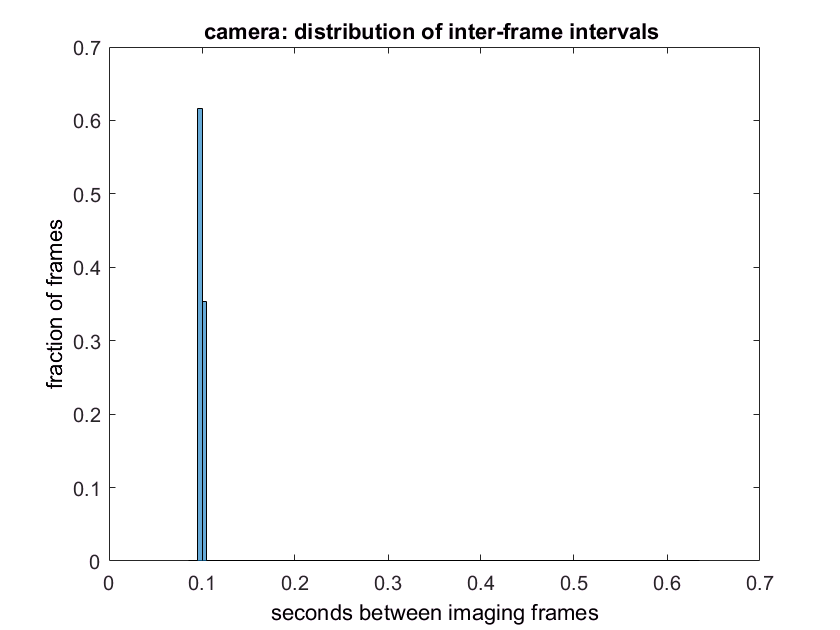


% HISTO
% histogram of dt

figure
% numBins = 10;
histogram(diffFrameT,'normalization','probability')
xlabel('seconds between imaging frames')
ylabel('fraction of frames')
clear titleText
titleText = 'camera: distribution of inter-frame intervals';
title(sprintf('%s ',titleText))


% how many trials over 0.12 Hz and how many under?:
idxDiffFrameToverPt12 = find(diffFrameT>0.12);
idxDiffFrameTunderPt12 = find(diffFrameT<0.12);

% percentanges
numIdxDiffFrameToverPt12 = length(idxDiffFrameToverPt12);
numIdxDiffFrameTunderPt12 = length(idxDiffFrameTunderPt12);

percentIdxDiffFrameToverPt12 = (numIdxDiffFrameToverPt12/length(diffFrameT))*100;
display(sprintf('percentage of dt greater than 0.12 sec: %0.00f',percentIdxDiffFrameToverPt12))

percentage of dt greater than 0.12 sec: 3


percentIdxDiffFrameTunderPt12 = (numIdxDiffFrameTunderPt12/length(diffFrameT))*100;
display(sprintf('percentage of dt less than 0.12 sec: %0.00f',percentIdxDiffFrameTunderPt12))

percentage of dt less than 0.12 sec: 97



idxDiffFrameTunderPt09 = find(diffFrameT<0.09);
numIdxDiffFrameTunderPt09 = length(idxDiffFrameTunderPt09);
percentIdxDiffFrameTunderPt09 = (numIdxDiffFrameTunderPt09/length(diffFrameT))*100;
display(sprintf('percentage of dt less than 0.09 sec: %0.00f',percentIdxDiffFrameTunderPt09))

percentage of dt less than 0.09 sec: 0



numImagingFramesSlipped = length(idxDiffFrameToverPt12) % raw num frames that slipped

numImagingFramesSlipped = 1363

diffBetweenSlippedImagingFrames = diff(idxDiffFrameToverPt12)'; % number of frames apart each slipped frame is
% ^ seems a different distance between frames/indicies that slip up each time...
meanDiffBetweenSlippedImagingFrames = mean(diffBetweenSlippedImagingFrames,2)

meanDiffBetweenSlippedImagingFrames = 32.9853

sterrDiffBetweenSlippedImagingFrames = std(diffBetweenSlippedImagingFrames,[],2)/sqrt(length(diffBetweenSlippedImagingFrames))

sterrDiffBetweenSlippedImagingFrames = 0.6035

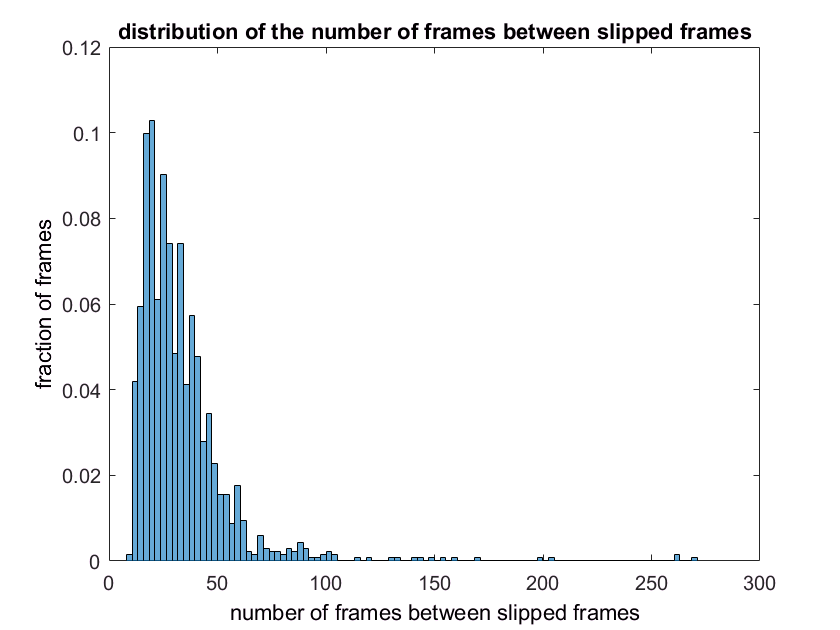


% plot DIST for dt between slipped frames
figure
numBins = 100;
histogram(diffBetweenSlippedImagingFrames,numBins,'normalization','probability')
title('distribution of the number of frames between slipped frames')
xlabel('number of frames between slipped frames')
ylabel('fraction of frames')


slippedDtValues = diffFrameT(idxDiffFrameToverPt12)'; % the actual dt values over 0.12
meanSlippedDtValues = mean(slippedDtValues,2)

meanSlippedDtValues = 0.3441

sterrSlippedDtValues = std(slippedDtValues,[],2)/sqrt(length(slippedDtValues))

sterrSlippedDtValues = 0.0035

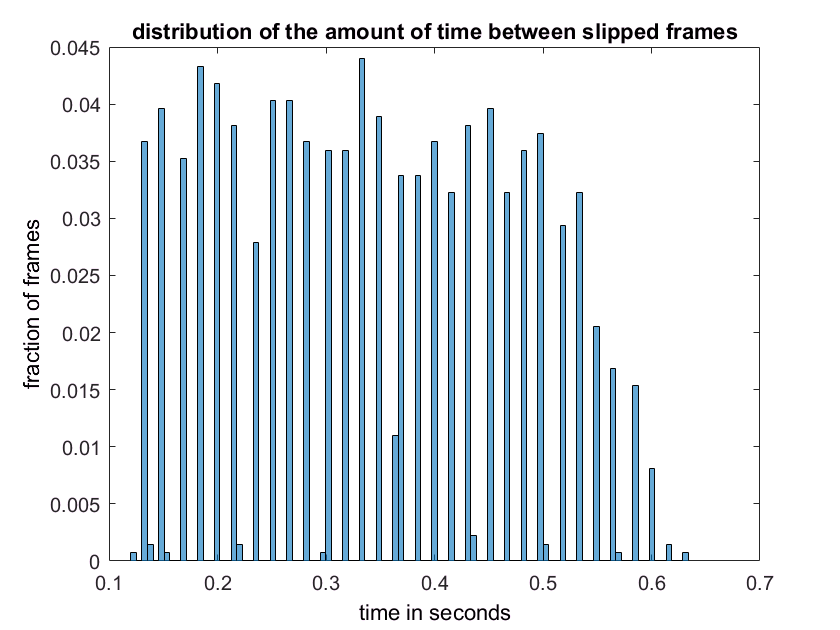


% plot DIST of actual slipped dt values 
figure
numBins = 100;
histogram(slippedDtValues,numBins,'normalization','probability')
title('distribution of the amount of time between slipped frames')
xlabel('time in seconds')
ylabel('fraction of frames')

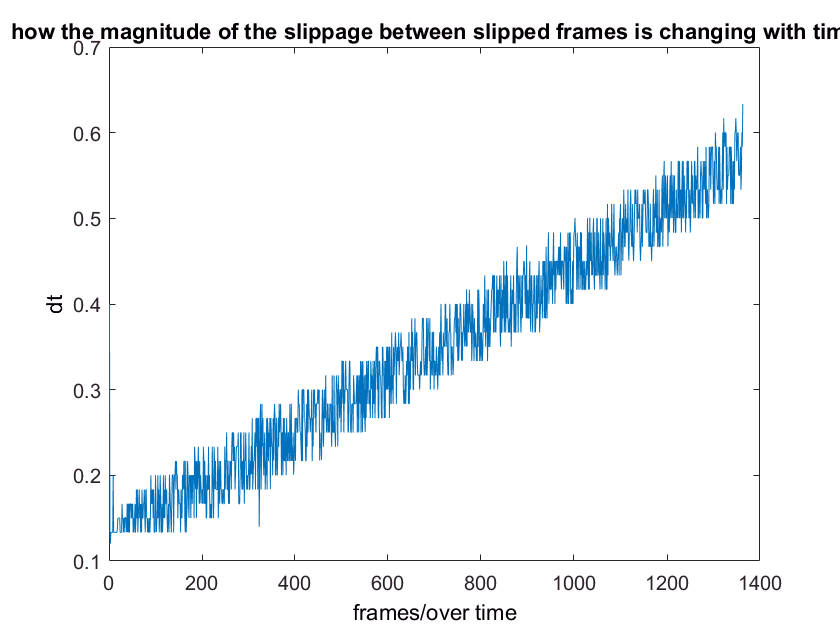


% PLOT differnce in time (not frames) between slipped frames (diffFrameT), vs frames
figure
clear x_axis
x_axis = [1:length(slippedDtValues)]; % x axis is frames
plot(x_axis,slippedDtValues)
xlabel('frames/over time')
ylabel('dt')
title('how the magnitude of the slippage between slipped frames is changing with time')

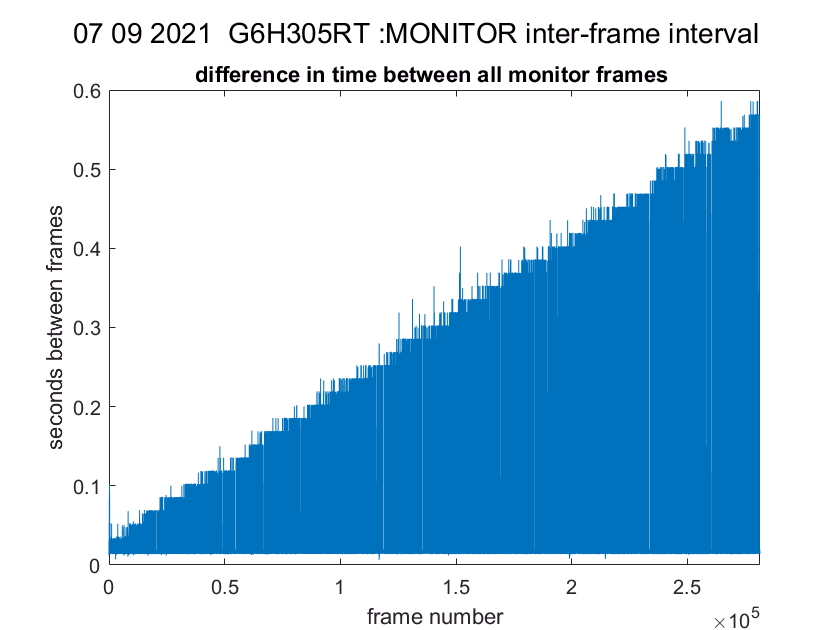

% same, for MONITOR RATE (allResp)
% -> so originally i had to look at the mean difference in dt
% for each trial, but now I have my 60 Hz timestamps vector to use

dtMonitorFrames = diff(timeStampsStopAndRespFramesAlltrialsMinusT0);

figure
clear titleText
titleText = ':MONITOR inter-frame interval';
suptitle(sprintf('%s ',date,subjName,titleText));

x_axis = [1:length(dtMonitorFrames)];
plot(x_axis,dtMonitorFrames)
xlim([0 length(dtMonitorFrames)])
%ylim([0 0.02])
xlabel('frame number')
ylabel('seconds between frames')
clear titleText
titleText = 'difference in time between all monitor frames';
title(sprintf('%s ',titleText))

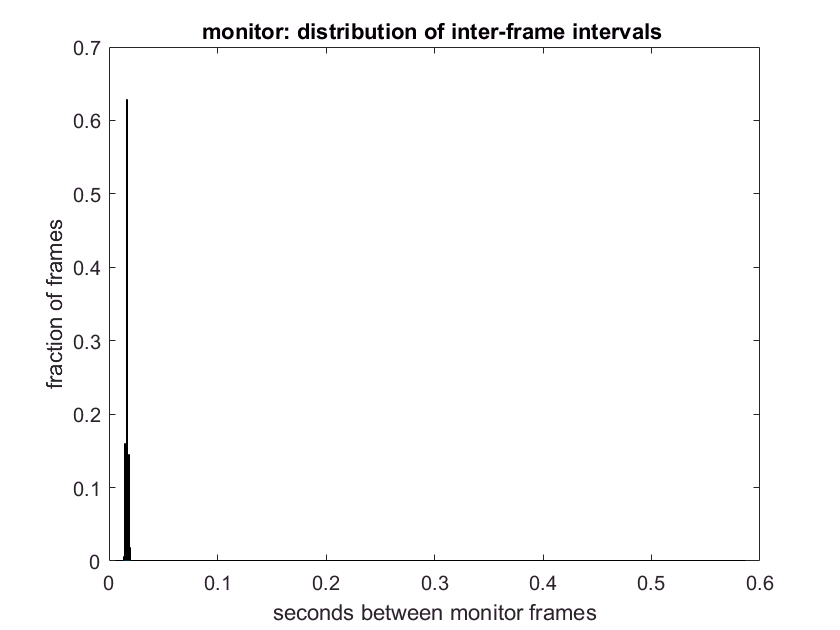


% HISTO MONITOR FRAMES

figure
% numBins = 10;
histogram(dtMonitorFrames,'normalization','probability')
xlabel('seconds between monitor frames')
ylabel('fraction of frames')
clear titleText
titleText = 'monitor: distribution of inter-frame intervals';
title(sprintf('%s ',titleText))  


clear idxAllRespOverPt18
clear idxAllRespUnderPt18
clear idxAllRespUnderPt16

idxAllRespOverPt18 = find(dtMonitorFrames>0.018);
idxAllRespUnderPt18 = find(dtMonitorFrames<0.018);

numIdxAllRespOverPt18 = length(idxAllRespOverPt18);
numIdxAllRespUnderPt18 = length(idxAllRespUnderPt18);

percentIdxAllRespOverPt18 = (numIdxAllRespOverPt18/length(dtMonitorFrames))*100;
display(sprintf('percentage of dt greater than 0.018 sec: %0.00f',percentIdxAllRespOverPt18))

percentage of dt greater than 0.018 sec: 17



percentIdxAllRespUnderPt18 = (numIdxAllRespUnderPt18/length(dtMonitorFrames))*100;
display(sprintf('percentage of dt less than 0.018 sec: %0.00f',percentIdxAllRespUnderPt18))

percentage of dt less than 0.018 sec: 83



idxAllRespUnderPt16 = find(dtMonitorFrames<0.016);
numIdxAllRespUnderPt16 = length(idxAllRespUnderPt16);
percentIdxAllRespUnderPt16 = (numIdxAllRespUnderPt16/length(dtMonitorFrames))*100;
display(sprintf('percentage of dt less than 0.016 sec: %0.00f',percentIdxAllRespUnderPt16))

percentage of dt less than 0.016 sec: 17



numIdxAllRespOverPt18

numIdxAllRespOverPt18 =        47656


% interesting, number of monitor frames over 0.18 is reaally close 
% to the number of imaging frames...

dtMonitorFramesOverPt18 = dtMonitorFrames(idxAllRespOverPt18);
meanDtMonitorFramesOverPt18 = mean(dtMonitorFramesOverPt18,2)

meanDtMonitorFramesOverPt18 =    0.028086790859430


sterrDtMonitorFramesOverPt18 = std(dtMonitorFramesOverPt18,[],2)/sqrt(length(dtMonitorFramesOverPt18))

sterrDtMonitorFramesOverPt18 =      2.632313085191467e-04


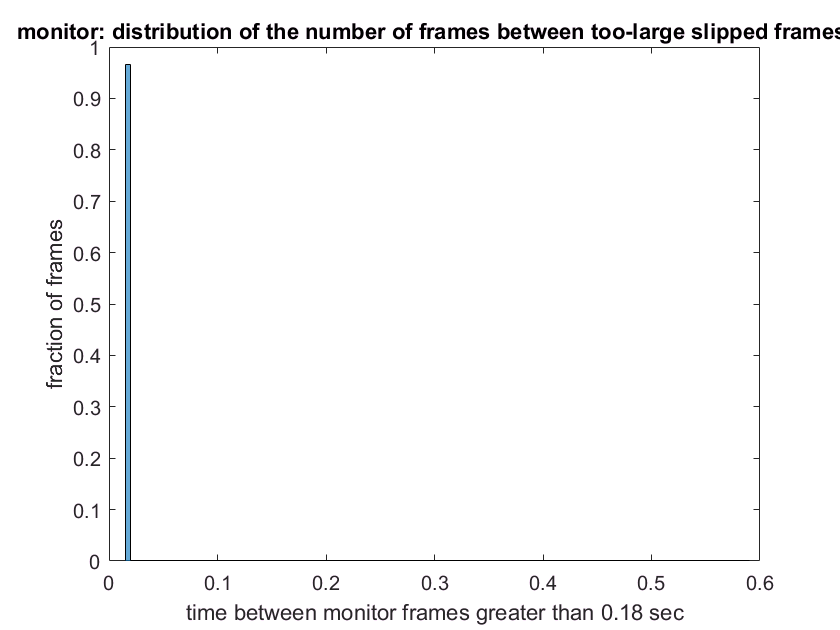


figure
% numBins = 10;
histogram(dtMonitorFramesOverPt18,'normalization','probability')
xlabel('time between monitor frames greater than 0.18 sec')
ylabel('fraction of frames')
clear titleText
titleText = 'monitor: distribution of the number of frames between too-large slipped frames';
title(sprintf('%s ',titleText))  


% ALMOST EVERY SLIPPED DT IS 6 FRAMES APART!!!
numFramesBetweenSlippedFramesTooLarge = diff(idxAllRespOverPt18)

numFramesBetweenSlippedFramesTooLarge =   Columns 1 through 1666


numFramesFramesBetweenSlippedFramesTooSmall = diff(idxAllRespUnderPt16)

numFramesFramesBetweenSlippedFramesTooSmall =   Columns 1 through 1666
